## Load SANS data

### Obtain matrix images from grasp depths

%{
SANSdata=load('GVS_SANS_grasp_data.mat'); %retrieve from original data (not included here)
grasp_data=SANSdata.grasp_data;
Im=grasp_data(1).data1{1,1}(:,:,1:181); %grasp_data(2): empty cell, grasp_data(3): blocked beam
BGR=grasp_data(2).data1{1,1}(:,:,1:181);
save('GVS_grasp_data.mat','Im','BGR')
%}

SANSdata=load('GVS_grasp_data.mat');
Im=SANSdata.Im;
BGR=SANSdata.BGR; 
I_0=Im-BGR;
save('I0_orig_1deg.mat','I_0')


## Image conditioning

%Center positions
c_x=61;
c_y=65;
pix_x=128;
pix_y=128;
Rmax=30; %forward scattered intensity
ratio=pix_x/pix_y;
sigma=2;
moving=20; %moving averaging window in the omega angle
[x,z,I_0_sm]=SANS_image_conditioning(I_0,c_x,c_y,pix_x,pix_y,Rmax,sigma,moving);

I_0_sm_5deg=zeros(size(I_0_sm,1),size(I_0_sm,2),floor(size(I_0_sm,3)/10));
for i=1:floor(size(I_0_sm,3)/10)
    I_0_sm_5deg(:,:,i)=I_0_sm(:,:,1+10*(i-1));
end
%x=0.5-c_x:1:pix_x-c_x-0.5;
%z=ratio*(0.5-c_y:1:pix_y-c_y-0.5); %rescale z axis due to detector resolution (ORNL: 256x192)
[X,Z]=meshgrid(x,z);
%[X,Z]=ndgrid(x,z);


### Test image

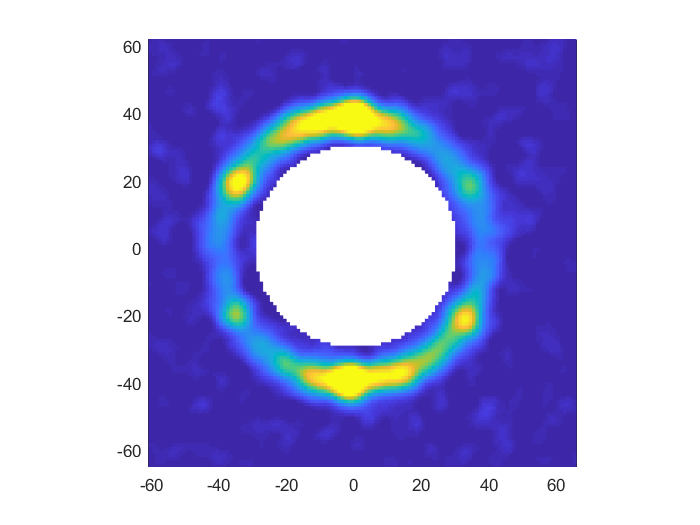

figure(12)
cla
pcolor(X,Z,I_0_sm_5deg(:,:,21)); shading flat;
caxis([0,1])
axis square

## Append SANS intensity maps to a cylindrical grid

### Separate the two halves of the inensity map in each angular slice

I_right=I_0_sm_5deg(:,c_x+1:end,:);

xr=0.5:1:66.5;
zr=ratio*(0.5-c_y:1:pix_y-c_y-0.5); %rescale z axis due to detector resolution (ORNL: 256x192)
[Xr,Zr]=meshgrid(xr,zr);
%[Xr,Zr]=ndgrid(xr,zr);

I_left=I_0_sm_5deg(:,c_x:-1:1,:);
xl=0.5:1:60.5;
zl=ratio*(0.5-c_y:1:pix_y-c_y-0.5); %rescale z axis due to detector resolution (ORNL: 256x192)
[Xl,Zl]=meshgrid(xl,zl);
%[Xl,Zl]=ndgrid(xl,zl);


### Create cylindrical grid for original data

%GRIDS
phi_deg=-100:5:260; phi_rad=phi_deg*pi/180;
r=0.5:1:60.5;
z=ratio*(0.5-c_y:1:pix_y-c_y-0.5);
[phimesh,rmesh,zmesh]=ndgrid(phi_rad,r,z);


### Assign the intensity data to the cylindrical grid

I_cyl=cat(3,I_right(:,1:61,1:36),I_left(:,:,1:37));
I_cyl=permute(I_cyl,[3,2,1]);


#### Test cylindrical intensity map

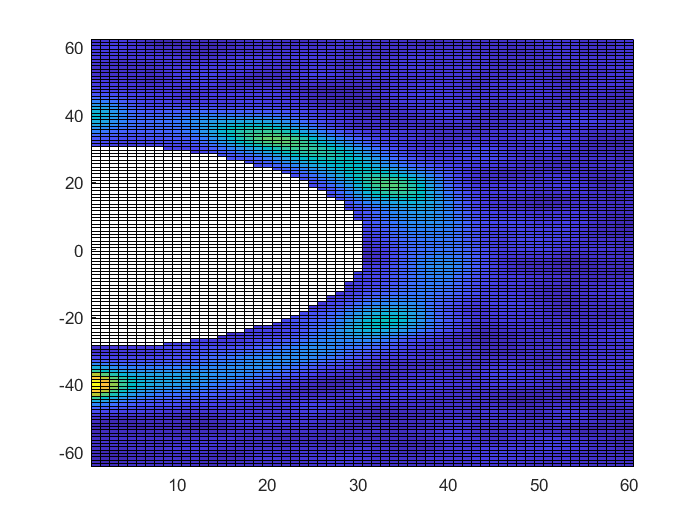

figure(15)
ind=35; %indey of phi coordinate
cla
X=squeeze(rmesh(ind,:,:));
Y=squeeze(zmesh(ind,:,:));
I=squeeze(I_cyl(ind,:,:));
pcolor(X,Y,I);

## Convert cylindrical grid to a Cartesian grid

### Original cylindrical grid in Cartesian coordinates

The original cylindrical grid is expressed as cartesian coordinates. Note that the resulting grid is not spaced uniformly.

[X_cyl,Y_cyl,Z_cyl]=pol2cart(phimesh,rmesh,zmesh); %original cylindrical grid in Cartesian coordinates

#### Save grid and corresponding SANS intensity

save('Cylinder_mesh_1deg_cart.mat','X_cyl','Y_cyl','Z_cyl') %Save Cyl grid in Cartesian coordinates
save('GVS_volumetric_polar_1deg_sm_2.mat','I_cyl') %Save original volumetric data on Cyl grid
I_temp=load('GVS_volumetric_polar_1deg_sm_2.mat','I_cyl'); 
I_cyl=I_temp.I_cyl;

### New equidistant Cartesian grid inside the cylinder

A new Cartesian grid is created which has equidistant spacing in qx,qy,qz for later interpolation

%Cartesian grid inside the cylinder
xcart=-50:1:50; 
ycart=-50:1:50; 
zcart=-50:1:50; 
%zcart=0.5-c_y:1:pix_y-c_y-0.5;
[Xc,Yc,Zc]=ndgrid(xcart,ycart,zcart);
save('Cartesian_mesh.mat','Xc','Yc','Zc')

## Interpolate data to the grids

### Interpolate SANS intensity data for the new equidistant Cartesian grid expressed in Cartesian coordinates

Interpolation is time consuming, data is saved already

I_cart_cartint=griddata(X_cyl,Y_cyl,Z_cyl,I_cyl,Xc,Yc,Zc); %interpolation according to Cartesian metric

save('GVS_volumetric_cart_1deg_sm_2.mat','I_cart_cartint')
I_temp=load('GVS_volumetric_cart_1deg_sm_2.mat','I_cart_cartint');
I_cart_cartint=I_temp.I_cart_cartint;

### Interpolate SANS intensity data for the new equidistant Cartesian grid expressed in Cylindrical coordinates

[Phi_c,R_c,Z_c]=cart2pol(Xc,Yc,Zc);
I_cart_cylint=griddata(phimesh,rmesh,zmesh,I_cyl,Phi_c,R_c,Z_c);
save('GVS_volumetric_cyl_1deg_sm_2.mat','I_cart_cylint')
I_temp=load('GVS_volumetric_cyl_1deg_sm_2.mat','I_cart_cylint');
I_cart_cylint=I_temp.I_cart_cylint;


## Save relevant grid and SANS intensity

I_cart_cartint=permute(I_cart_cartint,[2,1,3]);
Xc=permute(Xc,[2,1,3])/100; 
Yc=permute(Yc,[2,1,3])/100;
Zc=permute(Zc,[2,1,3])/100;
save('Cartesian_mesh_Lab.mat','Xc','Yc','Zc'); %meshgrid in [Qx,Qy,Qz] order in nm^-1 units 
save('GVS_intensity_raw.mat','I_cart_cartint'); %Raw intensity data in [Qx,Qy,Qz] order in arbitrary units

### Additional testing plots

%test plots
%{
figure(12)
cla
pcolor(X,Z,I_0(:,:,4)); shading flat;
caxis([0,70])
axis square

figure(13)
cla
pcolor(Xr,Zr,I_right(:,:,1)); shading flat;
caxis([0,70])

figure(14)
cla
xl=0.5:1:92.5;
zl=0.5-c_y:1:pix_y-c_y-0.5;
pcolor(Xl,Zl,I_left(:,:,1)); shading flat;
caxis([0,70])

figure(15)
ind=19;
cla
X=squeeze(rmesh(ind,:,:));
Y=squeeze(zmesh(ind,:,:));
I=squeeze(I_cyl(ind,:,:));
pcolor(X,Y,I);
%hold on
%contour(X,Y,I,[1,2,3,4,5,6],'Color','r');
shading flat;
caxis([0,70])
%}